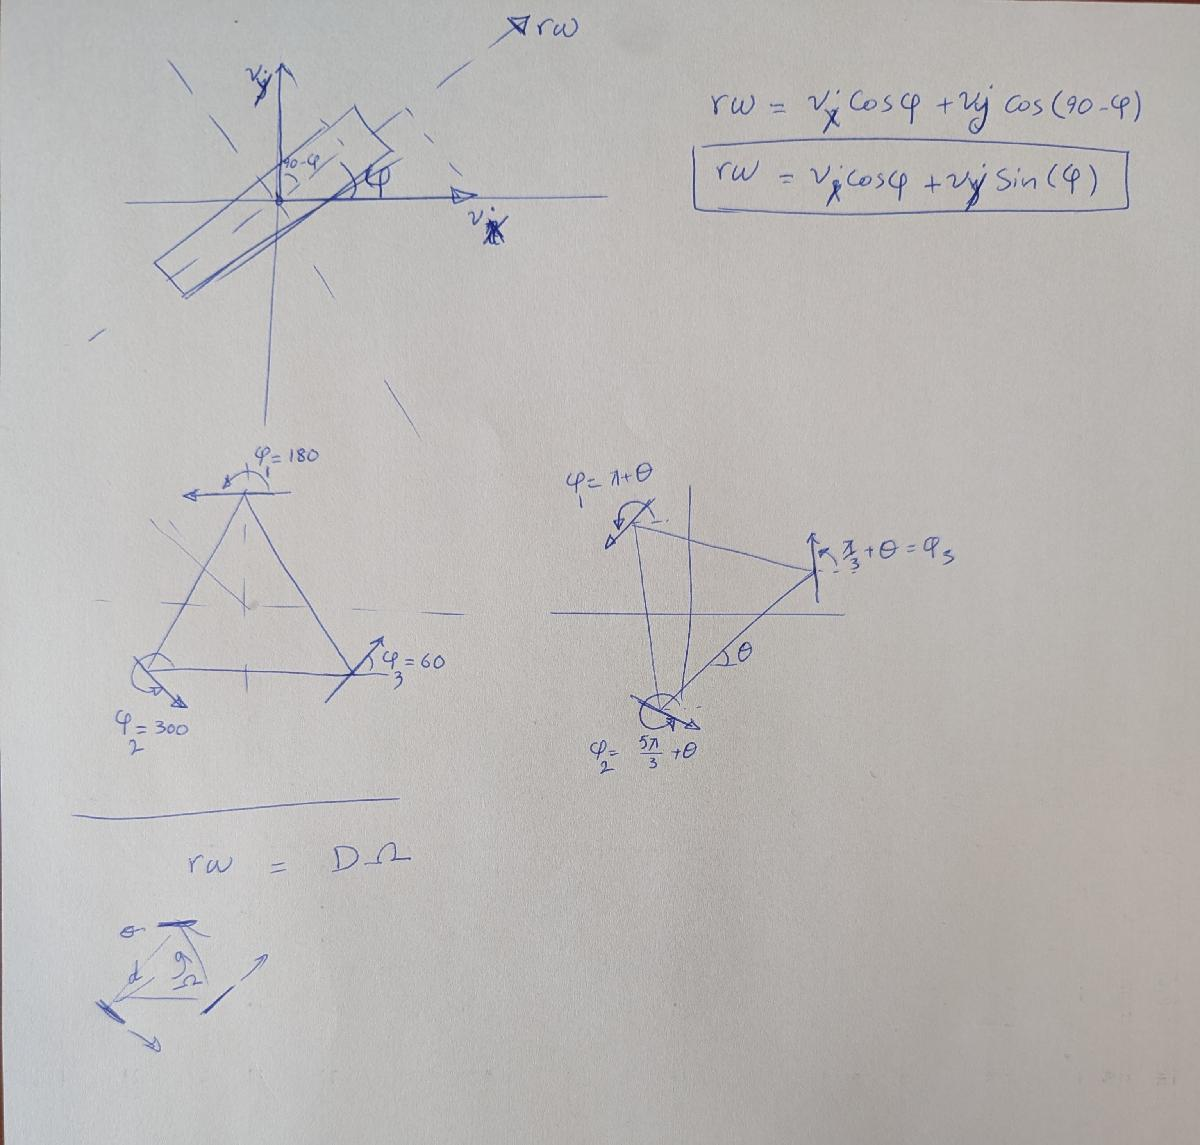

%%
clearvars

syms('phi', [3,1]);
syms theta % angle of each wheel relative to global X
syms('omega',[3,1]);
syms v_x v_y Omega
syms r D % r: radius of wheel. D: distance from robot center to wheel


phi1 = pi+theta;
phi2 = 5*pi/3 + theta;
phi3 = pi/3 + theta;

omegaEqs = 1/r * (v_x*cos(phi) + v_y*sin(phi) + D*Omega) ;
omegaEqs = subs(omegaEqs)

$$omegaEqs = \left(\begin{array}{c} -\frac{v_{x}\,\cos\left(\theta \right)+v_{y}\,\sin\left(\theta \right)-\text{D}\,\Omega }{r}\\ \frac{v_{x}\,\cos\left(\theta +\frac{5\,\pi }{3}\right)+v_{y}\,\sin\left(\theta +\frac{5\,\pi }{3}\right)+\text{D}\,\Omega }{r}\\ \frac{v_{x}\,\cos\left(\theta +\frac{\pi }{3}\right)+v_{y}\,\sin\left(\theta +\frac{\pi }{3}\right)+\text{D}\,\Omega }{r} \end{array}\right)$$


J_inv = equationsToMatrix(omegaEqs, [v_x; v_y; Omega]);

J_inv = simplify(J_inv)

$$J\_inv = \left(\begin{array}{ccc} -\frac{\cos\left(\theta \right)}{r} & -\frac{\sin\left(\theta \right)}{r} & \frac{\text{D}}{r}\\ \frac{\sin\left(\theta +\frac{\pi }{6}\right)}{r} & -\frac{\cos\left(\theta +\frac{\pi }{6}\right)}{r} & \frac{\text{D}}{r}\\ \frac{\cos\left(\theta +\frac{\pi }{3}\right)}{r} & \frac{\sin\left(\theta +\frac{\pi }{3}\right)}{r} & \frac{\text{D}}{r} \end{array}\right)$$


J = simplify(inv(J_inv))

$$J = \left(\begin{array}{ccc} -\frac{2\,r\,\cos\left(\theta \right)}{3} & \frac{2\,r\,\cos\left(\theta -\frac{\pi }{3}\right)}{3} & \frac{2\,r\,\cos\left(\theta +\frac{\pi }{3}\right)}{3}\\ -\frac{2\,r\,\sin\left(\theta \right)}{3} & -\frac{2\,r\,\cos\left(\theta +\frac{\pi }{6}\right)}{3} & \frac{2\,r\,\sin\left(\theta +\frac{\pi }{3}\right)}{3}\\ \frac{r}{3\,\text{D}} & \frac{r}{3\,\text{D}} & \frac{r}{3\,\text{D}} \end{array}\right)$$


matlabFunction(J,Optimize=true,File='HAMSTER_Jacobian')

ans = function_handle with value:
    @HAMSTER_Jacobian
